# MATH2089 Week 9

Suppose that we collect bivariate pairs of independent data $(X_1, Y_1)\dots,(X_n,Y_n)$. We want to determine how the response $Y$ is affected by the variable $X$—thus *regressing* $Y$ onto $X$. We might believe that there exists a functional relationship $f$ between the variables such that, on average, $Y = f(X)$. Formally, we  write $\mathbb{E}[Y\vert X] = f(X)$, so that, if we knew the value of $X$, we could predict the *average* value of $Y$. The simplest way to code this average prediction quality is to write $Y = f(X) + \varepsilon$, where $\varepsilon$ is a mean-zero random error. The practice of regression analysis is to then identify the *best estimate* for $f$. 

It is easiest to consider an affine relationship between $X$ and $Y$, ie, $Y = \beta_{0} + \beta_{1}X + \varepsilon$, so that $f(X) = \beta_{0} + \beta_{1}X$. Choosing the best $f$ is then equivalent to choosing the best pair $\beta_{0}$ and $\beta_{1}$. We might consider the chocie of $f$ that minimises the squared error between $Y$ and $f$, ie, 

$\text{Residual Sum of Squares} = \sum^{n}_{i = 1} \left(Y_{i} - f(X_{i})\right)^{2} = \sum^{n}_{i = 1} \left(Y_{i} - \left[\beta_{0} + \beta_{1}X_{i}\right]\right)^{2} = \sum^{n}_{i = 1} \varepsilon^{2}_{i}$.

This is known as least squares regression since we try to find values for $\beta_{0}$ and $\beta_{1}$ the produce the least value for the sum of the squares of the residuals/errors. When there is only one regressor (read: independent variable), this is know as simple linear regression. The term *linear* refers to the fact that we have a linear combination of parameters $\beta_{0}$ and $\beta_{1}$—not for the fact that $f$ represents a line. 

## Question 1

Let's examine how rainfall might affect runoff in a river. 

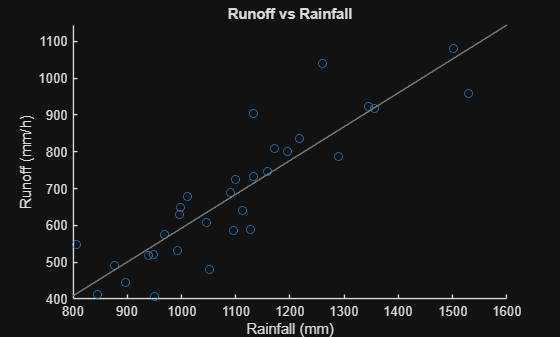

[rainfall, runoff] = readvars("data/rain.txt");

figure(1)
scatter(rainfall, runoff)
lsline() % add the best least squares line to the scatterplot
xlabel("Rainfall (mm)")
ylabel("Runoff (mm/h)")
title("Runoff vs Rainfall")

From the graph we can see that `runoff` tends to grow proportionally to `rainfall`. It appears as though we could approximate the overall trend between `rainfall` and `runoff` by a straight line, with random deviations above and below that line. We can verify this by running `lsline()`, which plots the *line of best fit*. Remember, we don't actually know that $\beta_0$ and $\beta_{1}$ are, so we need to estimate them from the data—recall estimators. For simple linear regression, we know that the best estimators for our coefficients are

$\hat{\beta}_{0} = \overline{Y} - \hat{\beta}_{1}\overline{X}$ and

$\hat{\beta}_{1} = \frac{\sum^{n}_{i = 1}\left(X_{i} - \overline{X}\right)\left(Y_{i} - \overline{Y}\right)}{\sum^{n}_{i = 1}\left(X_{i} - \overline{X}\right)^{2}}$.

We can pass on all of this to the function `fitlm()`. 

rainMod = fitlm(rainfall, runoff); %fitlm(X::predictor, Y::response)
rainMod.Coefficients

ans = 2×4 table
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -327.12       99.568    -3.2854     0.0026651
    x1             0.91946     0.089285     10.298    3.3758e-11


The column *Estimate* identifies the value of the estimator from our data. Here $\hat{\beta}_{0} = -327.1249$ and $\hat{\beta}_{1} = 0.9195$. Thus, the equation of our fitted line (using `lsline()`) is 

`runoff = -327.1249 + 0.9195 `$\times$ `rainfall`.

This implies that for each additional millimitre increase in `rainfall`, we expect to see a 0.9195 mm/h increase in `runoff`. What happens if we have no `rainfall`? Does this make sense?

Recall that the estimate for the model is computed from minimsing the contribution of the random errors. We might want to evaluate our random errors. In general, we wish to check that the variance of the raw residuals and their distribution. 

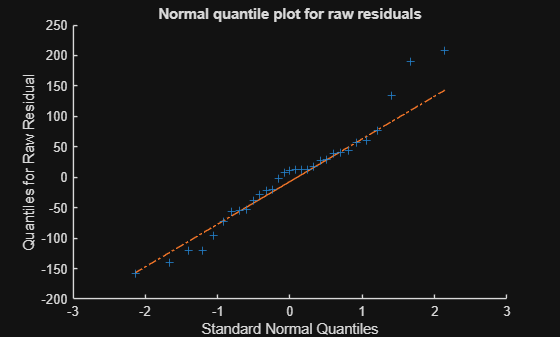

figure(2)
qqplot(rainMod.Residuals.Raw)
title("Normal quantile plot for raw residuals")
ylabel("Quantiles for Raw Residual")


rainMod.RMSE % estimate for the standard deviation of our errors

ans = 86.6856

std(rainMod.Residuals.Raw) % using the usual computation for standard deviation

ans = 85.2286

The quantile plot indicates that the residuals are approximately Normally distributed, although there are 3 outliers in the right tail. Remember that the fitted residuals $\hat{\varepsilon} = Y - \hat{Y}$ indicate the deviation between the actual response $Y$ and its estimate on the line $\hat{Y}$. The estimate for the standard deviation of the random errors is

$\hat{\sigma}^{2} = \frac{1}{n - p}\sum^{n}_{i = 1} \left(Y_{i} - \hat{Y}_{i}\right)^{2}$.

Note that we have $n - p$ degrees of freedom here, instead of the usual $n - 1$, where $p$ is the number of parameters that we are fitting ($p = 2$). The value $\hat{\sigma}$ provides an estimate for the variability of the whole model. We don't need to compute the average value of the fitted residuals since it is always zero—show this as an exercise.

Having established an estimate for the functional relationship between `rainfall` and `runoff`, we might want to evaluate if this relationship is statistically material—does `rainfall` actually influence `runoff`? If $\beta_{1} = 0$, then `rainfall` doesn't influence runoff. If $\beta_{1}\neq 0$, then `rainfall` does affect `runoff`—here we are only concerned if an effect exists, and not the size of the effect. Perhaps we can try a hypothesis test. Our hypotheses are


$$H_{0}: \beta_{1} = 0$$


$H_{1}: \beta_{1}\neq 0$. 

Recall that the residuals are Normally distributed. This implies that

$\hat{\beta}_{1} \sim N\left(\beta_{1}, \frac{\sigma}{\sqrt{\sum^{n}_{i = 1} \left(x_{i} - \overline{x}\right)^{2}}}\right) \Rightarrow T = \frac{\hat{\beta}_{1} - \beta_{1}}{S_{\hat{\beta}_{1}}}\sim t_{n - p}$. 

The observed value and p-value for our test statistic is in the table provided by `rainMod.Coefficients`. Here we observe $t_{\text{obs}} = 10.298$ and its p-value is approximately $10^{-11}$. Hence we have very strong evidence that `rainfall` affects `runoff`, and we reject $H_{0}$ at the 5% significance level. We can obtain a 95% confidence interval from our previous `rainMod` object. 

rainMod.coefCI % each row corresponds to the parameters

ans =  -530.7639 -123.4858
    0.7368    1.1021


The total variation in our model is $SS_{\text{tot}} = \sum^{n}_{i = 1} \left(Y_{i} - \overline{Y}\right)^{2}$. The amount of variation that is attributed to the model is $SS_{\text{reg}} = \sum^{n}_{i = 1} \left(\hat{Y}_{i} - \overline{Y}\right)^{2}$. The quantity


$$R^{2} = \frac{SS_{\text{reg}}}{SS_{\text{tot}}}$$


describes what percentage of the variation in response is explained by variation in the model. This is a metric for the quality of our model—the closer to 1 the better our model. In our example, we observe that 79% of the variation in `runoff` is explained by variation in `rainfall`. 

rainMod.Rsquared.Ordinary % use ordinary R-squared, not adjusted

ans = 0.7853

Correlation is another metric which assesses how well two variables fit a straight line. The closer to 1 or -1, the more closely the data fits a straight line. In simple linear regression, R-squared is equal to the square of the correlation!

corr(rainfall, runoff)

ans = 0.8862

corr(rainfall, runoff)^2

ans = 0.7853

We make the following assumptions when performing a simple linear regression

- There are no errors in the predictors.

- The responses are linear combinations of the *parameters* and responses—in cases where the parameters are not linear, we can usally apply a transformation on the predictor to make it so. This also means that the residual plot should appear random, like white noise. 

- The random errors have mean zero.

- The random errors are *homoscedastic—*the random errors have the same variance for each value of the predictor so that there is no *fanning* in the residual plot.

- The random errors are independent of the response and are uncorrelated with each other.

It is difficult to assess criteria one and five—we would need to look at the study design. Criterion two can be assessed through the scatter plot, while criteria 3 and 4 can be determined through the following residual plot. We want our plot to look completely random with no underlying patterns. This one looks pretty good. 

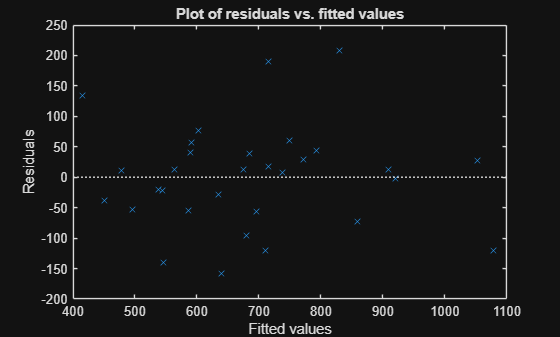

plotResiduals(rainMod, 'fitted')

## Question 2

Questions 2.a–2.f are essentially identical to question one. Hence, we'll look exclusively at 2.g.–2.h. 

[volume, protein] = readvars("data/milk.txt");

milkMod = fitlm(volume, protein)

milkMod = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat      pValue  
                   ________    _________    ______    _________

    (Intercept)     0.17558     0.046399    3.7841    0.0026043
    x1             0.024576    0.0015227    16.139    1.678e-09


Number of observations: 14, Error degrees of freedom: 12
Root Mean Squared Error: 0.042
R-squared: 0.956,  Adjusted R-Squared: 0.952
F-statistic vs. constant model: 260, p-value = 1.68e-09


chosenVolume = 30;

alpha = 0.01; % set 99% confidence interval
[proteinEstimate, proteinCI] = predict(milkMod, chosenVolume, 'alpha', alpha)

proteinEstimate = 0.9129

proteinCI =     0.8785    0.9472


The confidence interval gives us a plausible range of values for $f(30) = \beta_{0} + \beta_{1}\times 30$ given our observed data set. But what would happen if we added an additional data point $(X_{n+1}, Y_{n +1}) = (30, Y_{n+1})$? To construct a *prediction interval*, we need to add some additional variability to account for the variability of the new data point. Explicitly, we have

$\text{Var}\left(Y_{n + 1} - \left(\hat{\beta}_{0} + \hat{\beta}_{1}X_{n + 1}\right)\right) = \sigma^{2}\left(1 + n^{-1} + \frac{\left(X_{n + 1} - \overline{X}\right)^{2}}{\sum^{n}_{i = 1}\left(X_{i} - \overline{X}\right)^{2}}\right)$.

[proteinPrediction, proteinPI] = predict(milkMod, 30, 'alpha', 0.01, 'prediction', 'observation')

proteinPrediction = 0.9129

proteinPI =     0.7799    1.0458
